# MAE 509 Group Project


$$\begin{array}{l}
T\left(x\right)=c_1 e^{-\gamma \;x} +c_2 e^{\gamma \;x} +T_{\textrm{amb}} \\
\textrm{where}\\
\gamma =\sqrt{\frac{2\left(a+b\right)h}{\textrm{abk}}},\\
c_1 =-\frac{\Phi }{\textrm{ky}}\left\lbrack \frac{e^{\gamma \;L} \left(h+k\gamma \right)}{e^{-\gamma \;L} \left(h-k\gamma \right)+e^{\gamma \;L} \left(h+k\gamma \right)}\right\rbrack ,\\
c_2 =\frac{\Phi }{k\gamma \;}+c_1 
\end{array}$$


clc; clear

data_x = linspace(10, 66, 15);
data_T = [96.1 80.12 67.66 57.96 50.90 44.84 39.75 36.16 ...
    33.31 31.15 29.28 27.88 27.18 26.40 25.86];
data_std = [0.2 0.5 0.8 0.45 0.32 0.15 0.7 0.65 ...
    0.54 0.48 0.84 0.56 0.74 0.36 0.75];

% from lease-fit square to the data
phi = -18.41;
h = 0.00191;

param1 = [0.5 1.5]*phi;
param2 = [0.5 1.5]*h;

M = 5000; p = 2;
A = zeros(M, 2);
B = zeros(M, 2);
halton_set = net(haltonset(4), M)

halton_set =          0         0         0         0
    0.5000    0.3333    0.2000    0.1429
    0.2500    0.6667    0.4000    0.2857
    0.7500    0.1111    0.6000    0.4286
    0.1250    0.4444    0.8000    0.5714
    0.6250    0.7778    0.0400    0.7143
    0.3750    0.2222    0.2400    0.8571
    0.8750    0.5556    0.4400    0.0204
    0.0625    0.8889    0.6400    0.1633
    0.5625    0.0370    0.8400    0.3061


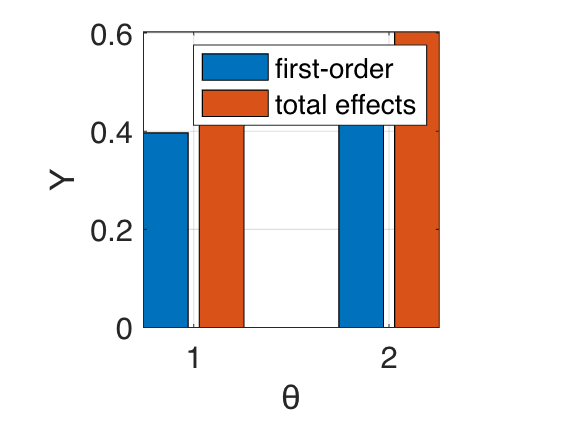


A(:,1) = param1(1) + (param1(2) - param1(1)).*halton_set(:, 1);
A(:,2) = param2(1) + (param2(2) - param2(1)).*halton_set(:, 2);

B(:,1) = param1(1) + (param1(2) - param1(1)).*halton_set(:, 3);
B(:,2) = param2(1) + (param2(2) - param2(1)).*halton_set(:, 4);

C = zeros(M,p,p);
for i = 1:p
    C(:,:,i) = B;
    C(:,i,i) = A(:,i);
end

%% Run the model and compute selected model output at sampled parameter
for  j = 1:M
    yA(j,1) = ss_sltn(A(j,:));
    yB(j,1) = ss_sltn(B(j,:));
    for i = 1:p
        yC(j,i) = ss_sltn(C(j,:,i));
    end
end

%% Compute sensitivity indices
f0  = mean(yA) ;
VARy = mean(yA.^2) - f0^2 ;

for i = 1:p
    yCi = yC(:,i);

	% fist order indices	
    Si(i)  = ( 1/M*sum(yA.*yCi) - f0^2 ) / VARy ; 
    % total effects indices
    STi(i) = 1 -  ( 1/M*sum(yB.*yCi) - f0^2 ) / VARy ;
end

%% Plot results
% sensitivity indices
indices = [Si' STi'];

figure
bar(indices)
axis square,xlabel('\theta'),ylabel('Y'), grid on		
set(gca,'FontSize',14)
legend('first-order', 'total effects')

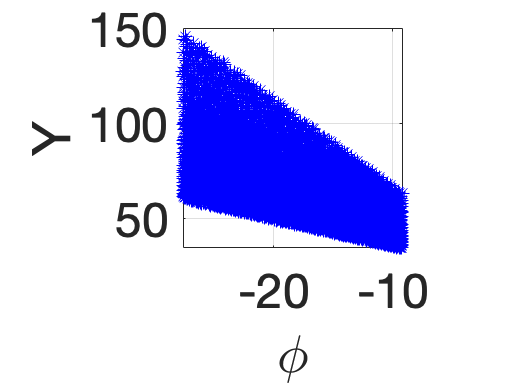


% scatter plots
figure
plot(A(:,1), yA, '*b')
axis square,xlabel('\phi'),ylabel('Y'), grid on		
set(gca,'FontSize',24)		

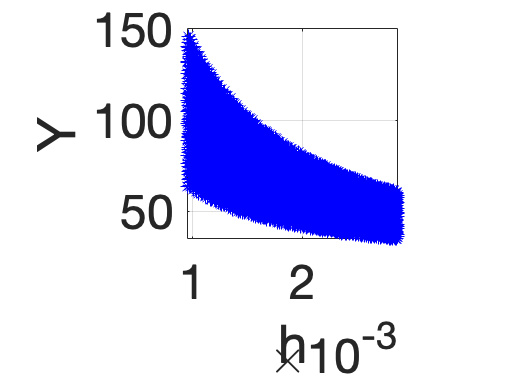

	
figure
plot(A(:,2), yA, '*b')
axis square,xlabel('h'),ylabel('Y'), grid on		
set(gca,'FontSize',24)	

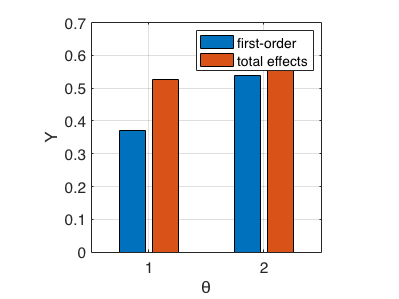

clear;
M = 5000; p = 2;

phi = -18.41;
h = 0.00191;

param1 = [0.5 1.5]*phi;
param2 = [0.5 1.5]*h;

D = zeros(M, 2);
E = zeros(M, 2);

D(:,1) = param1(1) + (param1(2) - param1(1)).*lhsdesign(M, 1);
D(:,2) = param2(1) + (param2(2) - param2(1)).*lhsdesign(M, 1);

E(:,1) = param1(1) + (param1(2) - param1(1)).*lhsdesign(M, 1);
E(:,2) = param2(1) + (param2(2) - param2(1)).*lhsdesign(M, 1);


F = zeros(M,p,p);
for i = 1:p
    F(:,:,i) = E;
    F(:,i,i) = D(:,i);
end

%% Run the model and compute selected model output at sampled parameter
for  j = 1:M
    yD(j,1) = ss_sltn(D(j,:));
    yE(j,1) = ss_sltn(E(j,:));
    for i = 1:p
        yF(j,i) = ss_sltn(F(j,:,i));
    end
end

%% Compute sensitivity indices
f0  = mean(yD) ;
VARy = mean(yD.^2) - f0^2 ;

for i = 1:p
    yFi = yF(:,i);

	% fist order indices	
    Si(i)  = ( 1/M*sum(yD.*yFi) - f0^2 ) / VARy ; 
    % total effects indices
    STi(i) = 1 -  ( 1/M*sum(yE.*yFi) - f0^2 ) / VARy ;
end

%% Plot results
% sensitivity indices
indices = [Si' STi'];

figure
bar(indices)
axis square,xlabel('\theta'),ylabel('Y'), grid on		
set(gca,'FontSize',14)
legend('first-order', 'total effects')

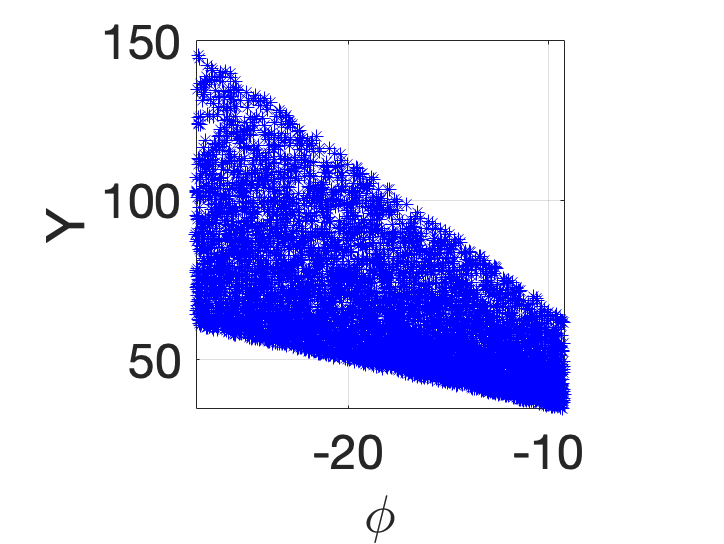


% scatter plots
figure
plot(D(:,1), yD, '*b')
axis square,xlabel('\phi'),ylabel('Y'), grid on		
set(gca,'FontSize',24)		

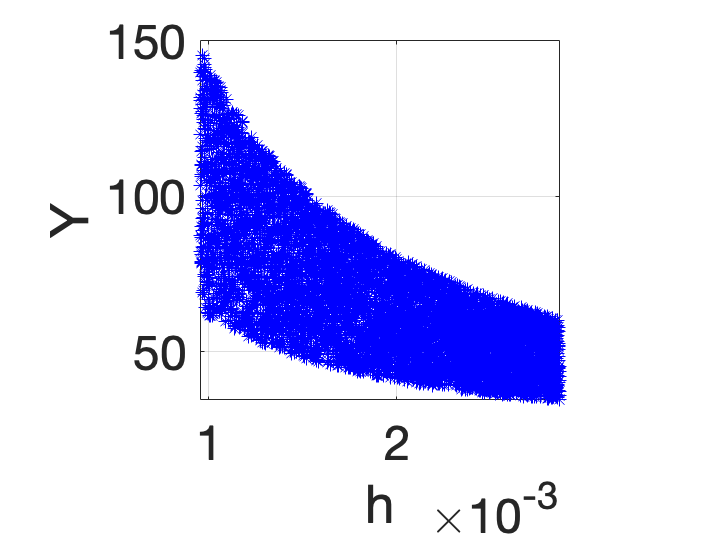

	
figure
plot(D(:,2), yD, '*b')
axis square,xlabel('h'),ylabel('Y'), grid on		
set(gca,'FontSize',24)	

function [T] = ss_sltn(input)
phi = input(1);
h = input(2);
a = 0.95; b = 0.95;
L = 70; x = 20;
k = 2.37;
Tamb = 21.29;

gamma = sqrt(2*(a+b)*h/a/b/k);
c1 = -phi/k/gamma * (exp(gamma*L)*(h+k*gamma))/((exp(-gamma*L)*(h-k*gamma) + exp(gamma*L)*(h+k*gamma)));
c2 = phi/k/gamma + c1;

T = c1 * exp(-gamma * x) + c2 * exp(gamma * x) + Tamb;

end